# 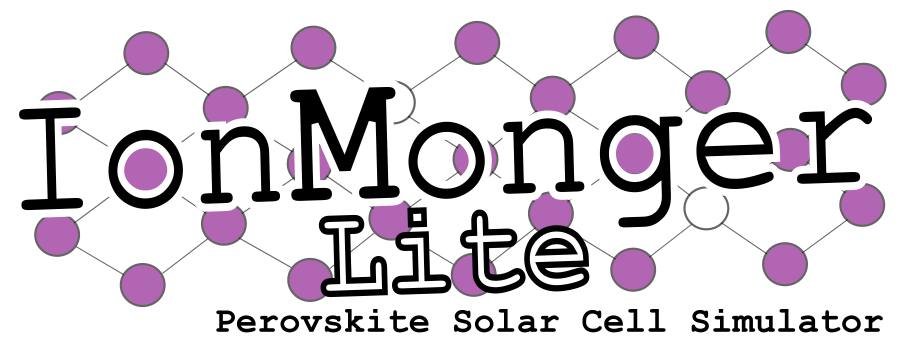

This live script is intended as a simple version of IonMonger that allows users to run basic simulation protocols without any expertise in MATLAB. The numerical solver used here is identical to the full version but users do not need to edit and format a parameters file in order to run simulations. Click 'Run' to begin the simulation. For the simplest user experience, ensure 'Hide Code' is selected under the 'VIEW' tab in MATLAB.

% This is a live script to enable users to run simple simulations without
% the need for any knowledge of MATLAB. This script replaces both
% parameters.m and master.m, compiling a parameters structure and calling
% numericalsolver.m to perform the simulation. Also included are some
% plotting functions to plot the simulation output.

clear; clc

% configure format settings for text
s = settings;
s.matlab.fonts.editor.normal.Size.PersonalValue = 13;
s.matlab.fonts.editor.normal.Name.PersonalValue = 'Calibri';
s.matlab.fonts.editor.normal.Color.PersonalValue = [0,0,0];

s.matlab.fonts.editor.heading1.Size.PersonalValue = 17;
s.matlab.fonts.editor.heading1.Name.PersonalValue = 'Calibri';
s.matlab.fonts.editor.heading1.Color.PersonalValue = [70, 122, 207];

s.matlab.fonts.editor.heading2.Size.PersonalValue = 15;
s.matlab.fonts.editor.heading2.Name.PersonalValue = 'Calibri';
s.matlab.fonts.editor.heading2.Color.PersonalValue = [1,1,1]*80;

tic;
starttime = datestr(now);
reset_path();


## Running simulations

Run simulations from this section. Choose a location to save the simulation data, select either a current-voltage sweep or impedance spectroscopy, and click 'Run' to begin.

 

workfolder = [ 'Data' '/']; % the folder to which data will be saved

experiment = 'impedance'; % determines the voltage protocol

fprintf('Beginning simulation at %s \n', datestr(now))

Beginning simulation at 12-Jan-2022 16:00:20 


### **Output plots**

If these boxes are checked, the corresponding plot will be generated and displayed below the live script.

plotoptions.protocol = true; % experimental protocol plot

For current-voltage sweeps:

plotoptions.jv = true; % current-voltage plot
plotoptions.jt = false; % current-time plot
plotoptions.phi = false; % electric potential
plotoptions.n = false; % electron density
plotoptions.p = false; % hole density
plotoptions.P = false; % anion vacancy density

For impedance spectroscopy:

plotoptions.nyquist = true; % Nyquist plot
plotoptions.bode = true; % Bode plot

### Animating the solution

Tick this box to automatically render a video of the sweep. This includes plots of current against applied voltage as well as carrier densities, electric potential and recombination rates against perpendicular distance into the device. This video will be saved as an mp4 file in the save folder. If the Image Processing Toolbox is installed, the video will be opened and played within the MATLAB movie player, otherwise an external player will be required. By default, videos have resolution 1920x1080p , frame rate 30fps and are 10s long. 

animate = false; 

% --- Parameter definitions ---


Verbose = false; % Verbose is set to false for simplicity but can be turned on 
% for debugging purposes
Stats       = 'off'; % ode15s option to output stats, either 'on' or 'off'
OutputFcn   = 'PrintVolt'; % ode15s optional message function, choose
% either 'PrintVolt' or 'PrintTime' (which can be found in Code/Common/)
% note that this option overwrites the previous two if Verbose=false
UseSplits   = true; % set this to false to make a single call to ode15s

% Resolution and error tolerances
N    = 400; % Number of subintervals, with N+1 being the number of grid points
rtol = 1e-6; % Relative temporal tolerance for ode15s solver
atol = 1e-10; % Absolute temporal tolerance for ode15s solver

% Physical constants
eps0  = 8.854187817e-12;  % permittivity of free space (Fm-1)
q     = 1.6021766209e-19; % charge on a proton (C)
Fph   = 1.4e21;           % incident photon flux (m-2s-1)
kB    = 8.61733035e-5;    % Boltzmann constant (eVK-1)

## Parameter input

Note that all permittivities must be given in units of $\varepsilon_0
$, the permittivity of free space.

### Perovskite parameters


T = 298;       % temperature (K)
b = 4e-7;       % perovskite layer width (m)
epsp = 24.1*eps0;       % permittivity of perovskite (Fm-1)
alpha = 13000000;     % perovskite absorption coefficient (m-1)
Ec    = -3.7;      % conduction band minimum (eV)
Ev    = -5.4;      % valence band maximum (eV)
Dn    = 0.00017;    % perovskite electron diffusion coefficient (m2s-1)
Dp    = 0.00017;    % perovskite hole diffusion coefficient (m2s-1)
gc    = 8.1e+24;    % conduction band density of states (m-3)
gv    = 5.8e+24;    % valence band density of states (m-3)

### Ion **parameters**

N0    = 1.6e+25;        % typical density of ion vacancies (m-3)
D     = @(Dinf, EA) Dinf*exp(-EA/(kB*T)); % diffusivity relation
DIinf = 6.5e-8;        % high-temp. vacancy diffusion coefficient (m2s-1)
EAI   = 0.58;          % iodide vacancy activation energy (eV)
DI    = D(DIinf, EAI); % diffusion coefficient for iodide ions (m2s-1)


Direction of light

inverted = false; % choose false for a standard architecture cell (light
% entering through the ETL), true for an inverted architecture cell
% (light entering through the HTL)


### ETL parameters

Effective doping density can be calculated from doping quasi-Fermi level by $d_E = g_c^E \exp \bigg( \frac{E_F^E-E_c^E}{k_BT} \bigg)$.

dE    = 1e+24;    % effective doping density of ETL (m-3) (choose <gcE/20)
gcE   = 5e+25;    % effective conduction band DoS in ETL (m-3)
EcE   = -4;    % conduction band minimum in ETL (eV)
bE    = 1e-7;  % width of ETL (m)
epsE  = 10*eps0; % permittivity of ETL (Fm-1)
DE    = 0.00001;    % electron diffusion coefficient in ETL (m2s-1)


### HTL parameters

Effective doping density can be calculated from doping quasi-Fermi level by $d_H = g_v^H \exp \bigg( - \frac{E_F^H-E_v^H}{k_BT} \bigg)$.

dH    = 1e+24;    % effective doping density of HTL (m-3) (choose <gvH/20)
gvH   = 5e+25;    % effective valence band DoS in HTL (m-3)
EvH   = -5.1;    % valence band maximum in HTL (eV)
bH    = 2e-7;  % width of HTL (m)
epsH  = 3*eps0;  % permittivity of HTL (Fm-1)
DH    = 0.000001;    % hole diffusion coefficient in HTL (m2s-1)


### Bulk recombination

tn    = 3e-9;    % electron pseudo-lifetime for SRH (s)
tp    = 3e-7;    % hole pseudo-lifetime for SRH (s)
beta  = 0;       % bimolecular recombination rate (m3s-1)


### Interface recombination

Recombination velocities should not exceed ~ 1e5.

betaE = 0;       % ETL/perovskite bimolecular recombination rate (m3s-1)
betaH = 0;       % perovskite/HTL bimolecular recombination rate (m3s-1)
vnE   = 100000;     % electron recombination velocity for SRH (ms-1)
vpE   = 10;      % hole recombination velocity for SRH (ms-1)
vnH   = 0.1;     % electron recombination velocity for SRH (ms-1)
vpH   = 100000;     % hole recombination velocity for SRH (ms-1)

%% Non-dimensionalise model parameters and save all inputs

% Compile all parameters into a convenient structure
vars = setdiff(who,{'params','vars'});
for i=1:length(vars), params.(vars{i}) = eval(vars{i}); end

% Non-dimensionalise the user-defined input parameters
warning('off','NoAuger:WarnID') % supress warning about Auger recombination
params = nondimensionalise(params);

% Unpack variables and functions needed in the rest of this function
[tstar2t, psi2Vap, Upsilon, Vbi] = struct2array(params, ...
    {'tstar2t','psi2Vap','Upsilon','Vbi'});


## Simulation protocol

% In order to make use of construct_protocol.m, instructions must be given
% in a specific order and format. Please see the GUIDE.md. Otherwise one
% can specify their own dimensionless functions of time (light and psi),
% dimensionless vectors (time and splits) and option whether to findVoc.

% Light protocol (either {a single value} or a protocol including an
% initial value, set to 1 for measurements in the light, 0 in the dark)
light_intensity = {1};

### Current-voltage sweep

This protocol begins in steady state, then simulates a preconditioning stage followed by a reverse and forward sweep to some target voltage at a constant sweep rate. The steady state initial voltage can either be a number (in Volts), the built-in voltage (Vbi) or open-circuit ('open-circuit').

if strcmp(experiment,'jv')
    prot_vals = {Vbi, ...
        5,...
        1.2, ...
        0.1, ...
        0};
    applied_voltage = ...
        {prot_vals{1}, ... % steady-state initial value
        'tanh', prot_vals{2}, prot_vals{3}, ...
        'linear', prot_vals{3}/prot_vals{4}, prot_vals{5}, ...
        'linear', prot_vals{3}/prot_vals{4}, prot_vals{3}};
elseif strcmp(experiment,'impedance')

### Impedance spectroscopy

This protocol measures the impedance at a number of sample frequencies, spaced logarithmically between the minimum and maximum. At each frequency, the cell will be held in steady state at the DC voltage for 10s, followed by 5 complete sine waves in applied voltage, with the last two periods being analysed to determine the impedance.

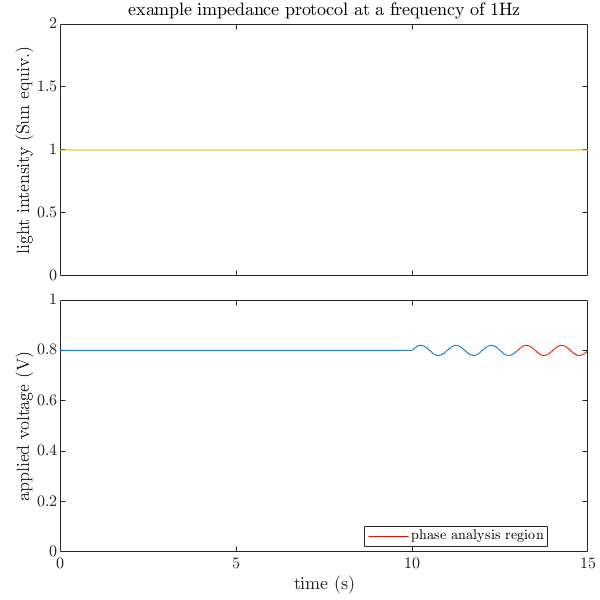

    applied_voltage = {'impedance',...
0.0001,...
100000000,...
0.8,...
0.02,...
60,...
        5}; % number of sine waves
    reduced_output = true;
end

% Choose whether the time points are spaced linearly or logarithmically
time_spacing = 'lin'; % set equal to either 'lin' (default) or 'log'


%% Create the simulation protocol and plot (if Verbose)

% Create the protocol and time points automatically, psi=(Vbi-Vap)/(2*kB*T)
[light, psi, time, splits, findVoc] = ...
    construct_protocol(params,light_intensity,applied_voltage,time_spacing);

% *** If defining one's own simulation protocol, define it here! ***

% Apply the options defined above
if inverted, inv = -1; else, inv = 1; end
if ~UseSplits, splits = time([1,end]); end

% Define the charge carrier generation function G(x,t)
G = @(x,t) light(t).*Upsilon./(1-exp(-Upsilon)).*exp(-Upsilon*(inv*x+(1-inv)/2));

if plotoptions.protocol
    figure()
    set(gcf,'Units','Pixels','Position',[200 200 600 600])
    ax1 = axes('Position',[10, 54, 88, 42]/100);
    plot(tstar2t(time),light(time),'Color',[0.93 0.69, 0.13])
    ylim([0,ceil(light(time(1)))+1])
    ax2 = axes('Position',[10, 8, 88, 42]/100);
    plot(tstar2t(time),psi2Vap(psi(time)));
    if strcmp(applied_voltage{1},'impedance')
        title(ax1,'example impedance protocol at a frequency of 1Hz','Interpreter','latex','FontSize',14);
    hold on
    plot(tstar2t(time(end-200:end)),psi2Vap(psi(time(end-200:end))),'r')
    legend({'','phase analysis region'},'Location','best','Interpreter','latex')
    hold off
    else
        title(ax1,'simulation protocol','Interpreter','latex','FontSize',14)
    end
    linkaxes([ax1,ax2],'x')
    xlabel(ax2,'time (s)','Interpreter','latex')
    ylabel(ax1,'light intensity (Sun equiv.)','Interpreter','latex')
    ylabel(ax2,'applied voltage (V)','Interpreter','latex')
    set(ax1,'TickLabelInterpreter','latex','XTickLabel',[],'FontSize',12)
    set(ax2,'TickLabelInterpreter','latex','FontSize',12)
    ylim([min([0,psi2Vap(psi(time))]), ceil(2*max(psi2Vap(psi(time))))/2])
end


%% Compile more parameters into the params structure
vars = setdiff(setdiff(who,fieldnames(params)),{'params','vars','i'});
for i=1:length(vars), params.(vars{i}) = eval(vars{i}); end

% Make the folder in which to save the output data (specified above)
if exist(workfolder,'dir')~=7, mkdir(workfolder); end


## Simulation status

The start and end time of the simulation will be displayed below. If the numerical solver encountered an error and could not return a solution, the error message will be displayed below.

fprintf('Computation started at %s\n', starttime);

Computation started at 12-Jan-2022 16:00:20



% Solve the equations
if strcmp(experiment,'jv')
    try
        sol = numericalsolver(params);
    catch ME
        rethrow(ME)
    end
elseif strcmp(experiment,'impedance')
    try
        sol = IS_solver(params);
    catch ME
        rethrow(ME)
    end
end

solving for steady state conditions at DC voltage 

Parallel computing toolbox detected 
Beginning impedance measurements on 6 workers 

frequency 1/60 solved in 2.8344s 
frequency 3/60 solved in 2.8157s 
frequency 4/60 solved in 2.7891s 
frequency 2/60 solved in 2.9318s 
frequency 5/60 solved in 2.9473s 
frequency 6/60 solved in 2.9923s 
frequency 11/60 solved in 2.8897s 
frequency 16/60 solved in 2.7434s 
frequency 21/60 solved in 2.9009s 
frequency 26/60 solved in 2.9234s 
frequency 31/60 solved in 3.0927s 
frequency 36/60 solved in 3.0619s 
frequency 10/60 solved in 2.6773s 
frequency 15/60 solved in 2.3925s 
frequency 20/60 solved in 2.9781s 
frequency 25/60 solved in 2.7461s 
frequency 35/60 solved in 2.9172s 
frequency 30/60 solved in 3.0698s 
frequency 14/60 solved in 2.5242s 
frequency 9/60 solved in 2.6714s 
frequency 19/60 solved in 3.0239s 
frequency 24/60 solved in 3.0401s 
frequency 34/60 solved in 2.9555s 
frequency 29/60 solved in 3.0552s 
frequency 8/60 solved in 2.702


disp('Simulation did not encounter any errors')

Simulation did not encounter any errors



% Save the data
save([params.workfolder,'simulation.mat'],'sol');

% Stop stopwatch and output nice message
fprintf('Completed simulation at %s, taking %s\n', ...
    datestr(now), secs2hms(toc) );

Completed simulation at 12-Jan-2022 16:00:54, taking 00:00:33


## Display output plots

Any requested output plots will be displayed here. These plots can be edited and exported here or opened in a separate window by clicking the arrow in the top right of each figure.

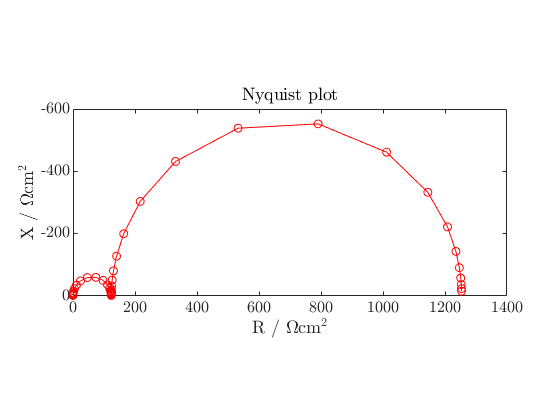

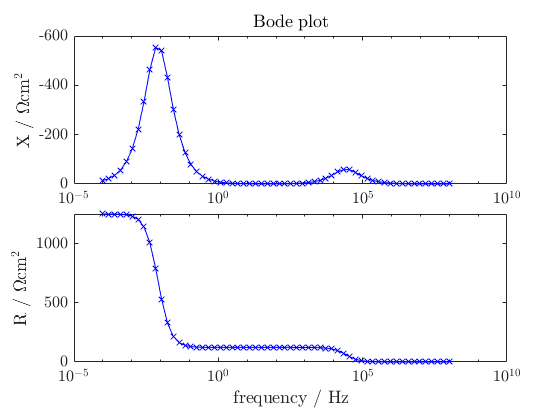


%% --- plot the output ---

fn = fieldnames(plotoptions);
for j = 2:numel(fn)
    if eval(['plotoptions.' fn{j}])
        try; eval(['get_' fn{j} '(sol);']); end
    end
end

## Video rendering status

If a video has been requested, the status of the render will be displayed below.

if animate && strcmp(experiment,'jv')
    vidstr = [workfolder, 'simulation'];
    fprintf('beginning video render \n')
    animate_sections(sol,[2:3],10,vidstr,'SupressOutput',true)
end

% Tidy the workspace
clearvars -except sol


function fig = get_jv(sol)
    if ~strcmp(sol.params.experiment,'jv'); error(); end
    fig = figure();
    i = 101:201; % exclude first section
    plot(sol.V(i),sol.J(i),'-r')
    hold on
    plot(sol.V(i(end):end),sol.J(i(end):end),'--r')
    hold off
    ylim([0 ceil(max(sol.J/5))*5])
    box on
    xlim([min([0; sol.V]), max(sol.V)])
    xlabel('applied voltage (V)','Interpreter','latex'); ylabel('current density (mAcm$^{-2}$)','Interpreter','latex');
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
    legend({'Reverse','Forward'},'Location','best','Interpreter','latex')
end

function fig = get_jt(sol)
    if ~strcmp(sol.params.experiment,'jv'); error(); end
    fig = figure();
    plot(sol.time,sol.J,'b')
    xlabel('time (s)','Interpreter','latex'); ylabel('current density (mAcm$^{-2}$)','Interpreter','latex');
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
end

function fig = get_phi(sol)
    if ~strcmp(sol.params.experiment,'jv'); error(); end
    figure()
    i = 101:20:201;
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'b-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot([sol.vectors.xE; sol.vectors.x; sol.vectors.xH],[sol.dstrbns.phiE(i,:),sol.dstrbns.phi(i,:),sol.dstrbns.phiH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,0,1;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electric potential (V)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'b-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot([sol.vectors.xE; sol.vectors.x; sol.vectors.xH],[sol.dstrbns.phiE(i,:),sol.dstrbns.phi(i,:),sol.dstrbns.phiH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,0,1;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electric potential (V)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
end

function fig = get_n(sol)
    if ~strcmp(sol.params.experiment,'jv'); error(); end
    figure()
    i = 101:20:201;
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'g-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot([sol.vectors.xE; sol.vectors.x],[sol.dstrbns.nE(i,:),sol.dstrbns.n(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,1,0;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electron density (m$^{-3}$)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'g-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot([sol.vectors.xE; sol.vectors.x],[sol.dstrbns.nE(i,:),sol.dstrbns.n(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,1,0;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electron density (m$^{-3}$)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
end

function fig = get_p(sol)
    if ~strcmp(sol.params.experiment,'jv'); error(); end
    figure()
    i = 101:20:201;
    col = [0.8, 0.2, 1];
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'],'Color',col)
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot([sol.vectors.x; sol.vectors.xH],[sol.dstrbns.p(i,:),sol.dstrbns.pH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('hole density (m$^{-3}$)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'],'Color',col)
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot([sol.vectors.x; sol.vectors.xH],[sol.dstrbns.p(i,:),sol.dstrbns.pH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('hole density (m$^{-3}$)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
end

function fig = get_P(sol)
    if ~strcmp(sol.params.experiment,'jv'); error(); end
    figure()
    i = 101:20:201;
    col = [1, 0, 0];
    plot(sol.vectors.x(1),sol.dstrbns.P(1,1),'-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'],'Color',col)
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.P(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot(sol.vectors.x,sol.dstrbns.P(i,:),'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('anion vacancy density (m$^{-3}$)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','lin','YLim',[0 max(max(sol.dstrbns.P))])
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.P(1,1),'-','DisplayName',['V = ' num2str(round(sol.V(i(1)),3),3) 'V'],'Color',col)
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.P(1,1),'k-','DisplayName',['V = ' num2str(round(sol.V(i(end)),3),3) 'V'])
    plot(sol.vectors.x,sol.dstrbns.P(i,:),'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('anion vacancy density (m$^{-3}$)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','lin','YLim',[0 max(max(sol.dstrbns.P))])
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
end

function fig = get_nyquist(sol)
    if ~strcmp(sol.params.experiment,'impedance'); error(); end
    figure()
    plot(sol.R,sol.X,'-or')
    set(gca,'TickLabelInterpreter','latex','FontSize',12,'DataAspectRatio',[1 1 1],'YDir','reverse')
    ylabel('X / $\Omega$cm$^2$','Interpreter','latex')
    xlabel('R / $\Omega$cm$^2$','Interpreter','latex')
    title(['Nyquist plot'],'Interpreter','latex')
end

function fig = get_bode(sol)
    if ~strcmp(sol.params.experiment,'impedance'); error(); end
    figure()
    T = tiledlayout(2,1);
    ax1 = nexttile;
    plot(ax1,sol.freqs,sol.X,'x-b')
    ax2 = nexttile;
    plot(sol.freqs,sol.R,'x-b')

    set(ax1,'XScale','log','TickLabelInterpreter','latex','FontSize',12,'YDir','reverse')
    set(ax2,'XScale','log','TickLabelInterpreter','latex','FontSize',12)

    ylabel(ax1,'X / $\Omega$cm$^2$','Interpreter','latex')
    ylabel(ax2,'R / $\Omega$cm$^2$','Interpreter','latex')
    xlabel(ax2,'frequency / Hz','Interpreter','latex')
    ylim(ax2,[0 inf])
    title(ax1,'Bode plot','Interpreter','latex')
    linkaxes([ax1,ax2],'x')

    T.TileSpacing = 'compact';
end